clear
load data.mat
load X.mat
load X_s.mat

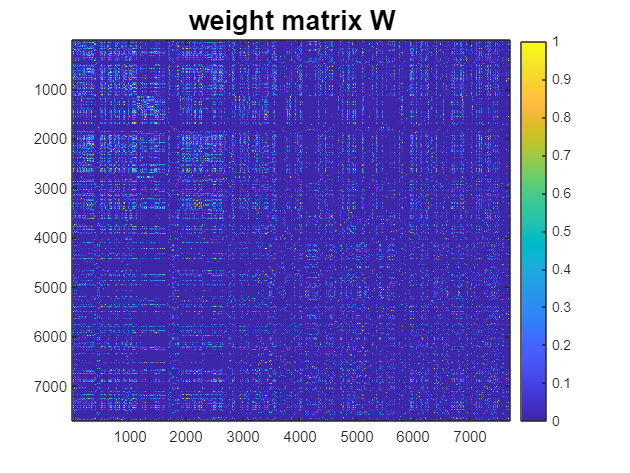

% first by type
X = normalize(X);
n = size(X,1);
r = 30;

type = data.Type;
truelabels = grp2idx(type); % numerical

squaredDists = squareform(pdist(X,'squaredeuclidean'));
subset = randsample(n,50);
[knnidx,knndists] = knnsearch(X, X(subset,:), 'K', r+1);
sigma = mean(knndists(:,end));
W = exp(-squaredDists/(2*sigma^2));
W(1:n+1:end) = 0; % set diagonals to zero
figure; % not required
imagesc(W); 
colorbar
title('weight matrix W','fontsize',18)

P = W ./ sum(W,2);
[V,Lambda] = eigs(P, 3, 'LM')

V =    -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000
   -0.0114   -0.0000   -0.0000


Lambda =     1.0000         0         0
         0    0.9856         0
         0         0    0.9834


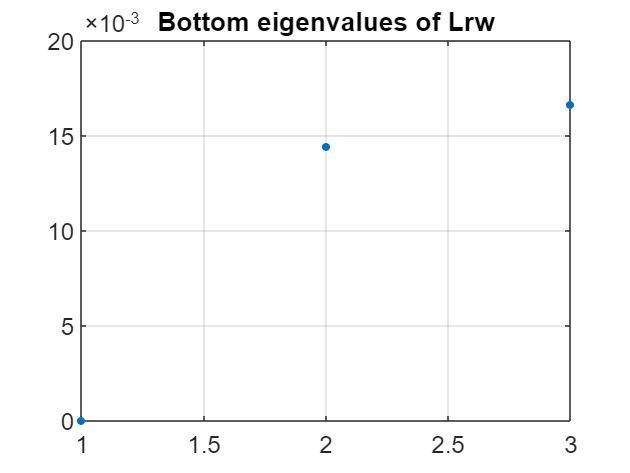

figure; % not required
plot(1-diag(Lambda), '.', 'markersize',16)
title('Bottom eigenvalues of Lrw', 'fontsize',18)
set(gca,'fontsize',16)
grid on

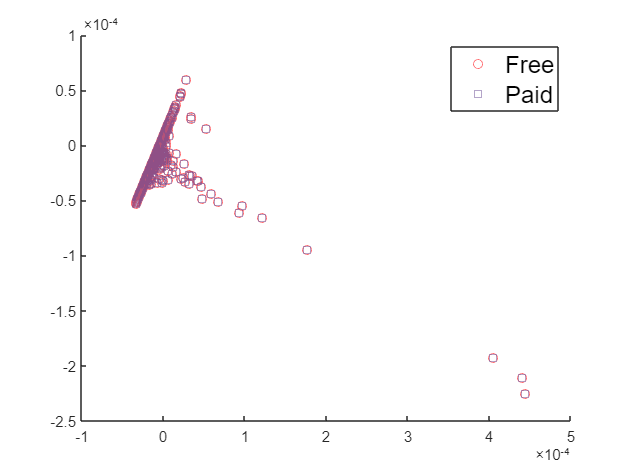

figure;
scatter(V(data.Type == type(1),2), ...
    V(data.Type == type(1),3),...
    36,ct(1,:),m(1));
hold on
scatter(V(data.Type == type(2),2), ...
    V(data.Type == type(2),3),...
    36,ct(2,:),m(2));
legend(unique(type),'fontsize',16)

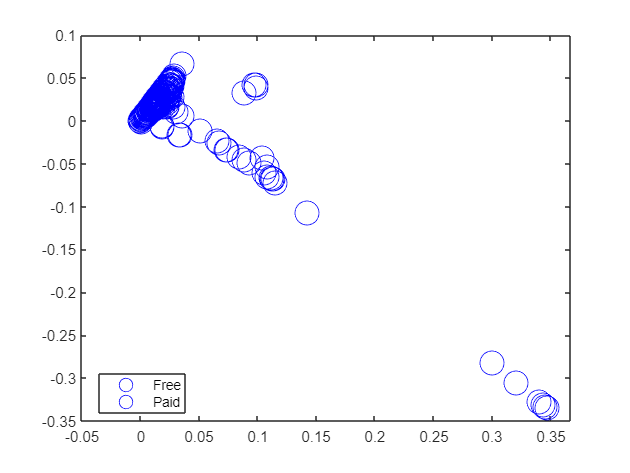

figure;
figure;
gscatter(V(:,2), V(:,3), type, 'rb', 'po', 16)

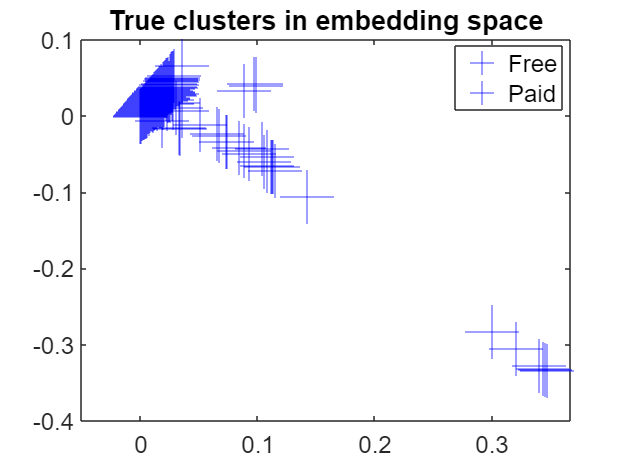


% for i=1:size(type,1)
%     scatter(V(find(data.Type == type(i)),2), ...
%         V(find(data.Type == type(i)),3),...
%         36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
%         'MarkerEdgeAlpha',.9,'LineWidth',0.8);
%     hold on
% end

figure;
gscatter(V(:,2), V(:,3), type,'rb','.+',36)
set(gca,'fontsize',16)
legend('fontsize',16)
title('True clusters in embedding space','fontsize',18)

%% Question 2 (14 points)
t = readtable('/Users/kimkiamco/Library/CloudStorage/OneDrive-Personal/San Jose State/MS DATA SCIENCE/2022 SPRING 1/MATH250/matlab/penguins_size.csv');
t([4 340],:) = [];
%island = categorical(t{:,2});
culmen_length = t{:,3};
culmen_depth = t{:,4};
flipper_length = t{:,5};
body_mass = t{:,6};
species = t{:,1}; % categorical
truelabels = grp2idx(species); % numerical
X = [culmen_depth culmen_length flipper_length body_mass];
X = normalize(X); % standardize the variables
n = size(X,1);
r = 3;
squaredDists = squareform(pdist(X,'squaredeuclidean')); % matrix of squared 
%pairwise Euclidean distances
subset = randsample(n,50);
[knnidx,knndists] = knnsearch(X, X(subset,:), 'K', r+1);
sigma = mean(knndists(:,end));
W = exp(-squaredDists/(2*sigma^2));
W(1:n+1:end) = 0; % set diagonals to zero
figure; % not required
imagesc(W); 
colorbar
title('weight matrix W','fontsize',18)

P = W ./ sum(W,2);
[V,Lambda] = eigs(P, 6, 'LM');
figure; % not required
plot(1-diag(Lambda), '.', 'markersize',16)
title('Bottom eigenvalues of Lrw', 'fontsize',18)
set(gca,'fontsize',16)
grid on

figure;
gscatter(V(:,2), V(:,3), species, 'rbm', 'po.', 16)
set(gca,'fontsize',16)
legend('fontsize',16)
title('True clusters in embedding space','fontsize',18)